clear all
load fisheriris


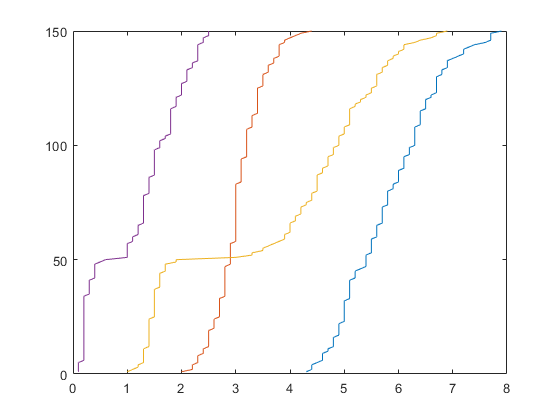

rng('default')
% rand(2,2);
[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexes= randperm(150);

plot(sort(meas()),(1:150))

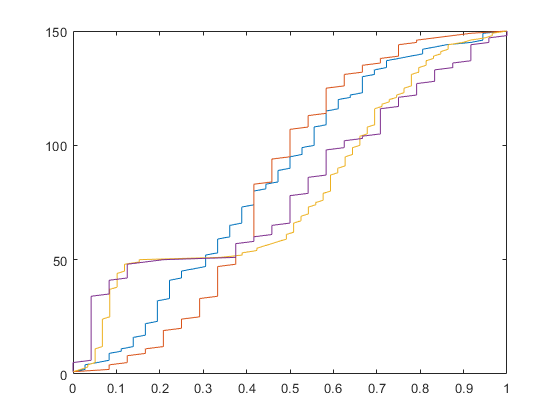

% histfit((meas(:,2)))

input = normalize(meas(indexes,:),'range');
plot(sort((input)), 1:150)

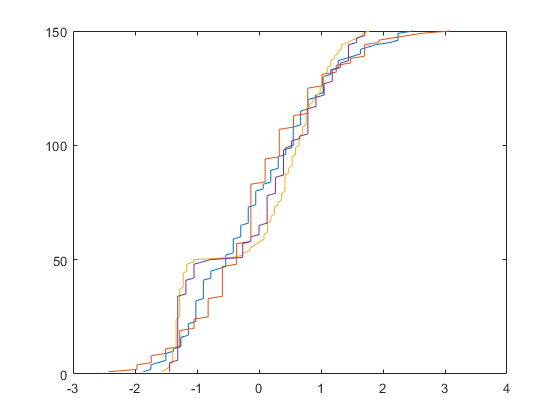


output = y(indexes,:);

input2 = normalize(meas(indexes,:));

g = (1 + exp(-1 * input2)) .^ -1;

plot(sort((input2)), 1:150)

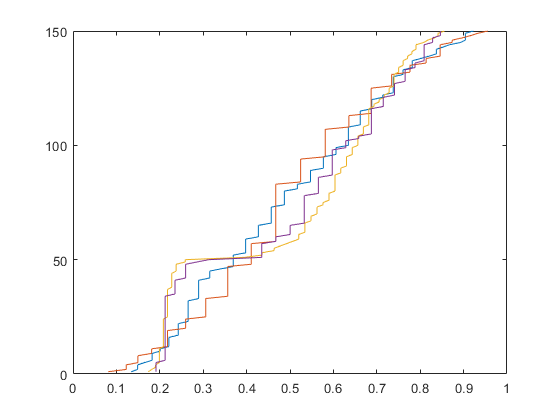

plot(sort((g)), 1:150)


testinput = g((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = g(1:batchsize,:);
out = output(1:batchsize,:);

n = 1;
% Vandermonde ----------
B=[]


B =

     []



for i = 1:batchsize
    
a=in(i,1).^[0:n];  % a = a/norm(a);
b=in(i,2).^[0:n];  % b = b/norm(b);
c=in(i,3).^[0:n];  % c = c/norm(c);
d=in(i,4).^[0:n];  % d = d/norm(d);

f= outproduct(a,b,c,d);
B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(n+1)^4 3])/100;

alpha=0.1 ;

tic
for i= 1:50
z1 = B*w;

expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);
sum(p1,2);
% p1 = max(min(p1, 0.95),0.05);
sumz=zeros(3,3);
d1 = p1-out;
w = pinv(B)*(z1-alpha*d1);
end
toc

Elapsed time is 0.023817 seconds.


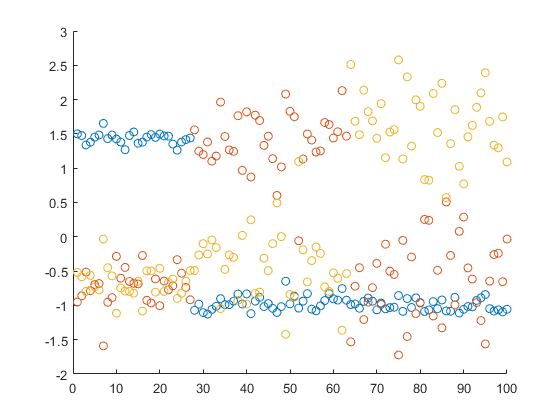


zy = z1; % B*w;
ay = p1;

zet=[];
zet(indexes(1:batchsize),:)=zy(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

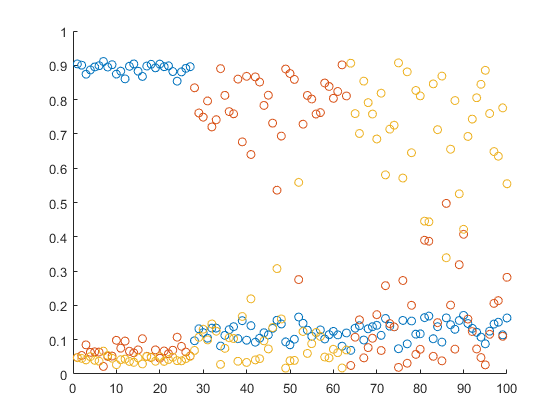


zet=[];
zet(indexes(1:batchsize),:)=ay(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

% TEST set


% Vandermonde ----------test
Btest=[]


Btest =

     []



for i = 1:50

a=testinput(i,1).^[0:n];   %a = a/norm(a);
b=testinput(i,2).^[0:n];   %b = b/norm(b);
c=testinput(i,3).^[0:n];   %c = c/norm(c);
d=testinput(i,4).^[0:n];   %d = d/norm(d);
f= outproduct(a,b,c,d);
Btest(i,:)=f(:)';
end

zytest = Btest*w;
exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

[M, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexes((end-49):end)));
sum(abs(misclassif))/50

ans = 0.0400

sum(abs(pytest-testoutput), 'all')/(50)

ans = 0.4204


C = confusionmat(I,ic(indexes((end-49):end)))

C =     23     0     0
     0    12     0
     0     2    13


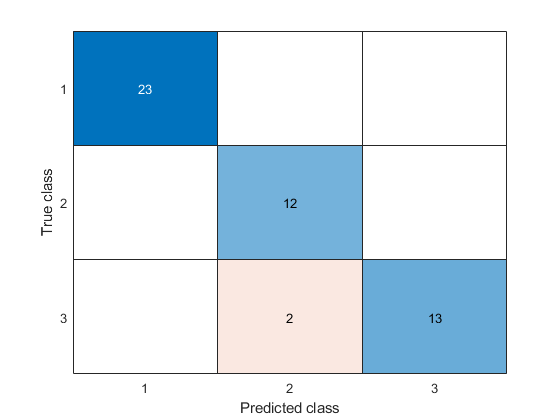

confusionchart(C);

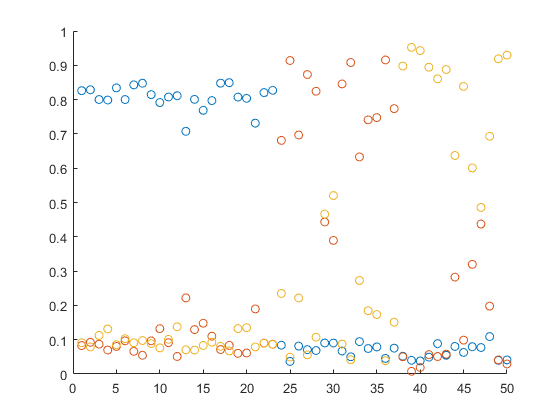


% scatter(1:50,misclassif);

zet=[];
zet(indexes((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:50,zet(:,1))
hold on
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off



% rataa = norm(y-output)/norm(output)






at = [0:0.1:1]'.^[0:5];   
plot(at)
for i = 1:11;
at(i,:)= at(i,:)/norm(at(i,:));
end
plot(at)


at = [-10:0.1:10]'.^[0:5];   a = a/norm(at)
plot(at)
for i = 1:201;
at(i,:)= at(i,:)/norm(at(i,:),1);
end
plot(at)